# form generation

clear all
%{
To generate a shape use alpha shape to make overall structure
%}

%%Wire Properties%% [Metric]
diameter = 1.29; %[mm]
barrel = 12,7; %[mm]

barrel = 12



%{
x is the points on the x axis
y is the points on the y axis

%}

x=[0;0;20;20]; %points in mm
y=[0;5;5;0]; %point in mm
smoothing=30; %smoothing of the shape

shp=alphaShape(x,y,smoothing);
plot(shp)
hold on
xlabel("distance x [mm]")
ylabel("distance y [mm]")
xmin=min(x);
xmax=max(x);
ymin=min(y);
ymax=max(y);
xlim([xmin,xmax]);
ylim([ymin,ymax]);
[X,Y]=meshgrid((xmin:diameter:xmax),(ymin:diameter:ymax))

X =          0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500
         0    1.2900    2.5800    3.8700    5.1600    6.4500    7.7400    9.0300   10.3200   11.6100   12.9000   14.1900   15.4800   16.7700   18.0600   19.3500


Y =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900    1.2900
    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800    2.5800
    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700    3.8700



in = inShape(shp,X,Y);
plot(X(in),Y(in),'r.')
plot(X(~in),Y(~in),'b.')
title(['Solenoid 2D profile with  ',num2str(sum(in,"all")),' wires at radius ', num2str(sum(diameter)), ' mm'])

%First plot done with shape and wires in solenoid shape


# 3d model generation

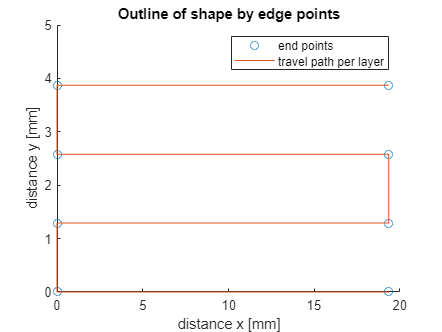



%{
goal is to use the in matrix as a guide of where the turns are per layer
and generate a unique solution to build the shape with the jumping turns
between layers
%}

%{
concept first layer will continue to have turns until logical matrix is
zero 

then as it jumps it will go simply up one and then work backwards to the
other end of the shape so the winding will look like the concept below for
the turns

    ------>|  over x end
  ^           up x
  |<-------  ...
          ^  up 1
--------->| over 1
%}

%{
for # of vertical layers (y)
    select at that layer:
    if odd {
        first point (x1#,y1#)
        Second point (x2#,y2#)
    } else
    {
        first point (x2#,y2#)
        Second point (x1#,y1#)
    }
        generate # of turns by (first-second)

    %%at this point layer # is completed in neccesary direction
    if(next layer [#+1 contains an 1 in {in}])
        determine lateral distance
        and vertical distance
        if odd {
            dist_lateral=(x2{#+1}-x1#)
            dist_vert=(y2{#+1}-y1#)
        }else{
            dist_lateral=(x1{#+1}-x2#)
            dist_vert=(y1({#+1}-11#)
        }
    generate layer between turn    
%}

sz=size(in);
layers_max=sz(1,1);
turn_max=sz(1,2);

x_points=zeros(1,1); %x point storage matrix
y_points=zeros(1,1); %y point storage matrix
dist=zeros(1,1); %dist  storage matrix
turns=zeros(1,1); %#of turns storage matrix

point_count=1;
for layer=1:1:layers_max %for all vertical layers
    if(rem(layer,2)==0) %for even layers

        for index=1:1:(turn_max) %start at low index and go over
            if(in(layer,index)==1) %find first point when in is 1
                first=[index,layer];
                break
            end
        end

        for index=(turn_max):-1:1 %start at high index and go back
            if(in(layer,index)==1)
                second=[index,layer];
                break
            end
        end
    %end of even layers
    else %for odd layers

        for index=1:1:(turn_max) %start at low index and go over
            if(in(layer,index)==1) %find first point when in is 1
                second=[index,layer];
                break
            end
        end

        for index=(turn_max):-1:1 %start at high index and go back
            if(in(layer,index)==1)
                first=[index,layer];
                break
            end
        end

    end %end odd layers
    x_point(1,point_count)=first(1,1);
    y_point(1,point_count)=first(1,2);
    point_count=point_count+1; %increment count
    x_point(1,point_count)=second(1,1);
    y_point(1,point_count)=second(1,2);
    point_count=point_count+1; %increment count
    turns(1,layer)=second(1,1)-first(1,1); %calculate # of turns per layer

    

    if(second(1,1)>first(1,1))
        turns(1,layer)=turns(1,layer)+1;
        dist(1,layer)=turns(1,layer).*1.29-1.29; %update into measured length
    else
        turns(1,layer)=turns(1,layer)-1;
        dist(1,layer)=turns(1,layer).*1.29+1.29; %update into measured length
    end

end
x_edges=(x_point-1).*diameter;
y_edges=(y_point-1).*diameter;
figure()
scatter(x_edges,y_edges)
xlabel("distance x [mm]")
ylabel("distance y [mm]")
title("Outline of shape by edge points")
xlim([xmin,xmax]);
ylim([ymin,ymax]);
hold on
plot(x_edges,y_edges)
legend('end points','travel path per layer')


%{
X_point and y_point are still based upon the in matrix and do not have any
distance calibration

x_edge and y_edge are converterted to distance

determine number of turns between points 1,2 and then jump to 3 iteratively

dist is from dist list
 %# turns= dist/diameter

%}

# plotting of overall shape of solenoid

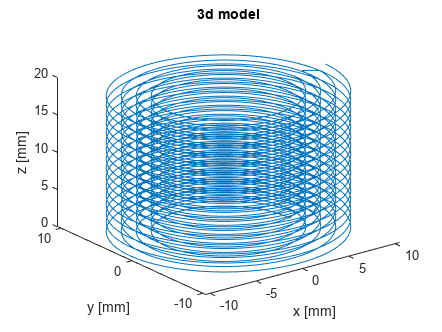

num_points=1:1000; %num points per layer
figure()



X_sol=zeros(1);
Y_sol=zeros(1);
Z_sol=zeros(1);


sol_r=(barrel/2)+diameter/2;%calculate wire diameter for first layer
for layer=1:1:layers_max %for each layer
    x_sol=sol_r.*cos(2.*pi.*(num_points/length(num_points)).*turns(1,layer)); %x radius solenoid diameter * cos (2pi*num_turn*(point)/(max points))
    y_sol=sol_r.*sin(2.*pi.*(num_points/length(num_points)).*turns(1,layer)); %y radius solenoid diameter * cos (2pi*num_turn*(point)/(max points))
    
    if(x_edges(1,(layer*2)-1)==x_edges(1,(layer*2))) %catch overlaps
        z_sol=x_edges(1,(layer*2))+diameter./num_points;
    else
        z_sol=x_edges(1,(layer*2)-1):dist(1,layer)/(length(num_points)-1):x_edges(1,(layer*2)); %vertical height steps, fails on single turns, caught by if
    end

    sol_r=sol_r+diameter; %increment diameter

    %straight jump between layers for ease of design
    if(layer==1) %first layer assign
        X_sol=x_sol;
        Y_sol=y_sol;
        Z_sol=z_sol;
    else %other layer append
        X_sol=[X_sol x_sol];
        Y_sol=[Y_sol y_sol];
        Z_sol=[Z_sol z_sol];
    end
     
end
    plot3(X_sol,Y_sol,Z_sol)
    hold on
    xlabel("x [mm]")
    ylabel("y [mm]")
    zlabel("z [mm]")
    title("3d model")

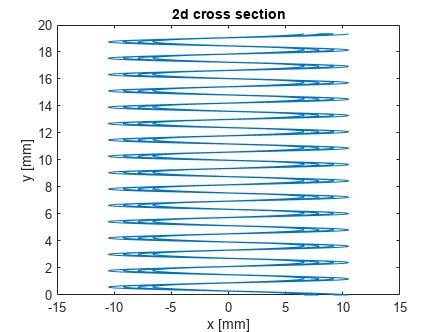


    figure()
    plot(X_sol(ceil(end/2), :),Z_sol(ceil(end/2), :))
    title("2d cross section")
    xlabel("x [mm]")
    ylabel("y [mm]")


    clearvars first second index layer sol_r smoothing sz x y X Y x_points y_points



# 3d fields

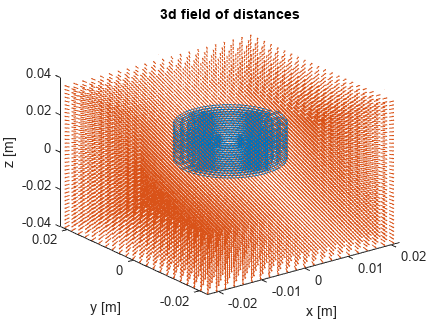

clear xmax ymax
xmax=max(X_sol); %xmax of solenoid
ymax=max(Y_sol); %ymax of solenoid
zmax=max(Z_sol); %zmax of solenoid

    
    %Inputs
current=300;%amps
s=2; %scaling of overall volume
d=2;  %step distance mm

%radius solenoid, is ocnstant in xy plane, xmax works
[X,Y,Z]=meshgrid(-d*round(s*xmax/d):d:d*round(s*xmax/d),-d*round(s*ymax/d):d:d*round(s*ymax/d),-d*round(s*zmax/d):d:d*round(s*zmax/d));
[RX,RY,RZ]=meshgrid(-d*round(s*xmax/d):d:d*round(s*xmax/d),-d*round(s*ymax/d):d:d*round(s*ymax/d),-d*round(s*zmax/d):d:d*round(s*zmax/d));
[HX,HY,HZ]=meshgrid(-d*round(s*xmax/d):d:d*round(s*xmax/d),-d*round(s*ymax/d):d:d*round(s*ymax/d),-d*round(s*zmax/d):d:d*round(s*zmax/d));



%stepping to Meter scaling
X=X/1000;
Y=Y/1000;
Z=Z/1000;

RX=RX/1000;
RY=RY/1000;
RZ=RZ/1000;

HX=HX/1000;
HY=HY/1000;
HZ=HZ/1000;


X_sol=X_sol/1000;
Y_sol=Y_sol/1000;
Z_sol=Z_sol/1000;
%stepping to Meter scaling done

%solenoid shape with radial vectors below
plot3(X_sol,Y_sol,Z_sol)
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
title("3d field of distances")
hold on

%point distances calculations
%calculate all H field points from all solenoid points
for step=1:1:length(Y_sol)-1 %for each segment of solenoid
    dl=[X_sol(1,step+1)-X_sol(1,step),Y_sol(1,step+1)-Y_sol(1,step),Z_sol(1,step+1)-Z_sol(1,step)];
    for x_step=1:size(X,2)-1 %for all x points, second index of meshgrid
        for y_step=1:size(Y,1)-1 %for all y points, first index of meshgrid
            for z_step=1:size(Z,3)-1%for all z points, third index of meshgrid
                %X_sol(1,step+1)-X_sol(1,step),Y_sol(1,step+1)-Y_sol(1,step)

                r=([X(y_step,x_step,z_step)-X_sol(1,step),Y(y_step,x_step,z_step)-Y_sol(1,step),Z(y_step,x_step,z_step)-Z_sol(1,step)]); %distance vector
                %distance vector {working}


                r_hat=r/vecnorm(r); %unit vector {working}

                %https://www.youtube.com/watch?v=BZ-FIdlBj9E&ab_channel=EMPossible


                RX(y_step,x_step,z_step)=RX(y_step,x_step,z_step)+r(1,1);
                RY(y_step,x_step,z_step)=RY(y_step,x_step,z_step)+r(1,2);
                RZ(y_step,x_step,z_step)=RZ(y_step,x_step,z_step)+r(1,3);
               

                hx=current/(4*pi)*(dl(1,2).*r(1,3)-dl(1,3).*r(1,2)).*vecnorm(r).^(-2);
                hy=current/(4*pi)*(dl(1,3).*r(1,1)-dl(1,1).*r(1,3)).*vecnorm(r).^(-2);
                hz=current/(4*pi)*(dl(1,1).*r(1,2)-dl(1,2).*r(1,1)).*vecnorm(r).^(-2);

                HX(y_step,x_step,z_step)=HX(y_step,x_step,z_step)+hx;
                HY(y_step,x_step,z_step)=HY(y_step,x_step,z_step)+hy;
                HZ(y_step,x_step,z_step)=HZ(y_step,x_step,z_step)+hz;

            end
        end
    end
end
quiver3(X,Y,Z,RX,RY,RZ)
hold off

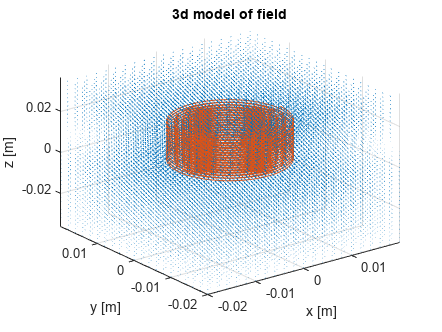


figure()
quiver3(X,Y,Z,HX,HY,HZ)
xlabel("x [m]")
ylabel("y [m]")
zlabel("z [m]")
title("3d field")
hold on
plot3(X_sol,Y_sol,Z_sol)
title("3d model of field")


% figure()
% plot(X_sol(ceil(end/2), :),Z_sol(ceil(end/2), :))
% title("2d cross section")
% xlabel("x [mm]")
% ylabel("z [mm]")


# Acceleration, Velocity Mapping


%acceleration dependent on distance             
                
%https://www.youtube.com/watch?v=loVSpD_OMjI&ab_channel=Engineer4Free
%https://math.stackexchange.com/questions/2986437/how-do-you-calculate-the-position-of-an-object-with-respect-to-time-given-an-acc